# **PRACTICE 7. F1-SCORE**

## Grado en Ingeniería Informática - Reconocimiento de Patrones

## Fernando M. Quintana Velázquez - Guillermo Bárcena González

# EXERCISE 1: UNDERSAMPLING

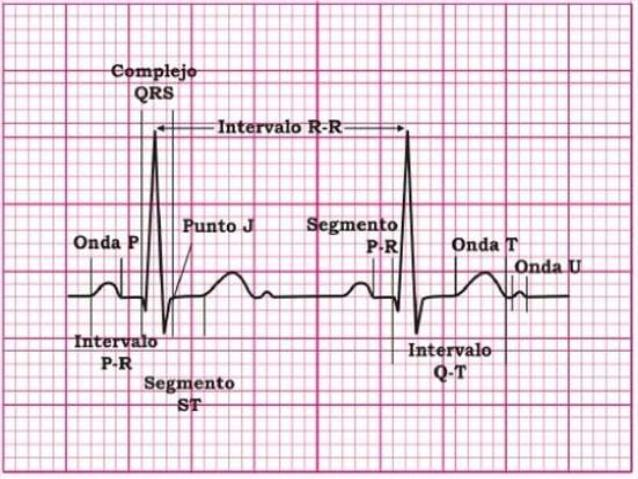

Using the global practice database '**Cardiac Recognition Systems**', perform the following actions:

a). Load the data contained in the file 'mitbih_train.csv' and create two variables. One variable called 'x_tr' will contain all the data from the first 187 columns and will represent the pattern of characteristics of each individual. The next variable called 'y_tr' will contain all the data from the last column, indicating the type of arrhythmia. (See global practice statement). 

Perform the same action for the file 'mitbih_test.csv' and create the variables x_ts and y_ts.

clear all;
data = csvread ('mitbih_train.csv');
test = csvread ('mitbih_test.csv');
x_tr=data(:,1:end-1)';
y_tr=data(:,end)';
x_ts=test(:,1:end-1)';
y_ts=test(:,end)';

b). To reduce computation time, shuffle the data and select the first half of the total characteristics from x_tr and x_ts variables and the first 10000 data from the training set.

[x_tr, y_tr] = shuffle(x_tr, y_tr);
[x_ts, y_ts] = shuffle(x_ts, y_ts);

n_variables = ceil(size(x_tr,1)/2);
x_tr_part = x_tr(1:n_variables,1:10000)';
x_ts_part = x_ts(1:n_variables,:)';
y_tr_part=y_tr(1,1:10000)';
y_ts_part=y_ts';

# EXERCISE 1: UNDERSAMPLING

c). Balanced the classes using the undersampling technique

Balancing Training Data:

%First we find out the number of clases:
number_clases = unique(y_tr_part)

number_clases =      0
     1
     2
     3
     4


%Now we find all entries from each class
class0_tr = find(y_tr_part == 0);
class1_tr = find(y_tr_part == 1);
class2_tr = find(y_tr_part == 2);
class3_tr = find(y_tr_part == 3);
class4_tr = find(y_tr_part == 4);

frequence_of_clases_tr = zeros(1,length(number_clases));
frequence_of_clases_tr(1) = length(class0_tr);
frequence_of_clases_tr(2) = length(class1_tr);
frequence_of_clases_tr(3) = length(class2_tr);
frequence_of_clases_tr(4) = length(class3_tr);
frequence_of_clases_tr(5) = length(class4_tr);

%show the number of elements for each class
frequence_of_clases_tr

frequence_of_clases_tr =         8269         263         658          75         735


length_min_class = min(frequence_of_clases_tr)

length_min_class = 75

%We reduce all clases to minimum number.In this example its class3
index0 = randperm(frequence_of_clases_tr(1));
class0_tr_cut = class0_tr(index0(1:length_min_class),1);

index1 = randperm(frequence_of_clases_tr(2));
class1_tr_cut = class1_tr(index1(1:length_min_class),1);

index2 = randperm(frequence_of_clases_tr(3));
class2_tr_cut = class2_tr(index2(1:length_min_class),1);

index3 = randperm(frequence_of_clases_tr(4));
class3_tr_cut = class3_tr(index3(1:length_min_class),1);

index4 = randperm(frequence_of_clases_tr(5));
class4_tr_cut = class4_tr(index4(1:length_min_class),1);

undersampled_data = sort([class0_tr_cut; class1_tr_cut; class2_tr_cut; class3_tr_cut; class4_tr_cut]);
x_tr_part_under = x_tr_part(undersampled_data, :);
y_tr_part_under = y_tr_part(undersampled_data, :);

Balancing Test Data:

%number of clases:
number_clases = unique(y_ts_part)

number_clases =      0
     1
     2
     3
     4


%Now we find all entries from each class
class0_ts = find(y_ts_part == 0);
class1_ts = find(y_ts_part == 1);
class2_ts = find(y_ts_part == 2);
class3_ts = find(y_ts_part == 3);
class4_ts = find(y_ts_part == 4);

frequence_of_clases_ts = zeros(1,length(number_clases));
frequence_of_clases_ts(1) = length(class0_ts);
frequence_of_clases_ts(2) = length(class1_ts);
frequence_of_clases_ts(3) = length(class2_ts);
frequence_of_clases_ts(4) = length(class3_ts);
frequence_of_clases_ts(5) = length(class4_ts);

%show the number of elements for each class
frequence_of_clases_ts

frequence_of_clases_ts =        18118         556        1448         162        1608


length_min_class = min(frequence_of_clases_ts)

length_min_class = 162

%We reduce all clases to minimum number.In this example its class3
index0 = randperm(frequence_of_clases_ts(1));
class0_ts_cut = class0_ts(index0(1:length_min_class),1);

index1 = randperm(frequence_of_clases_ts(2));
class1_ts_cut = class1_ts(index1(1:length_min_class),1);

index2 = randperm(frequence_of_clases_ts(3));
class2_ts_cut = class2_ts(index2(1:length_min_class),1);

index3 = randperm(frequence_of_clases_ts(4));
class3_ts_cut = class3_ts(index3(1:length_min_class),1);

index4 = randperm(frequence_of_clases_ts(5));
class4_ts_cut = class4_ts(index4(1:length_min_class),1);

undersampled_data = sort([class0_ts_cut; class1_ts_cut; class2_ts_cut; class3_ts_cut; class4_ts_cut]);
x_ts_part_under = x_ts_part(undersampled_data, :);
y_ts_part_under = y_ts_part(undersampled_data, :);

d). Plot the confusion matrix for a classifier using the kmeans algorithm and Euclidean distance for values of $k=3$. To calculate the $k$ centroids, use the training data, and to calculate the distances, use the test data and the centroids extracted from the training data.

For me it would make no sense at all to calculate kmeans with a value of k = 3 because there are 5 different clases in the dataset so im going to to use k = 5

[idx,Centroids] = kmeans(x_tr_part_under, 5);
len = length(y_ts_part_under);
prediction = zeros(len,1);
for i = 1:len
    distances = d_euclid(Centroids',x_ts_part_under(i,:)');
    [~,index] = min(distances);
    prediction(i)=index-1;%to get different clases
end

Ploting confusion Matrix:

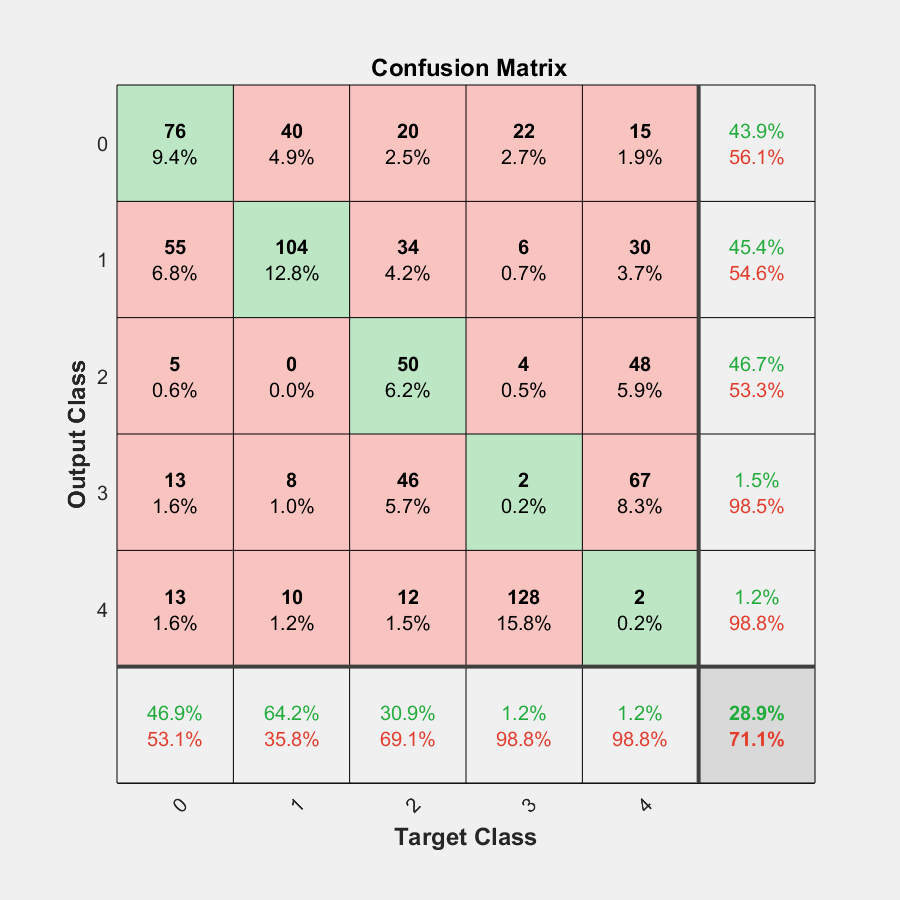

figure;
plotconfusion(categorical(y_ts_part_under'),categorical(prediction'));

e). Calculate the precision, recall and accuracy of each class and finally calculate the global F1-Score using the mean

confusion = confusionmat(categorical(prediction'),categorical(y_ts_part_under'));
precision = diag(confusion)./sum(confusion,2);
recall = diag(confusion)./sum(confusion,1)';
f1Scores = 2*(precision.*recall)./(precision+recall);
meanF1 = mean(f1Scores)

meanF1 = 0.2766

# EXERCISE 3: OVERSAMPLING

f). Balanced the classes using the oversampling technique, using the 2 nearest neighbours to each random pattern to generate the new one.

Lets start by balancing training data

frequence_of_clases_tr

frequence_of_clases_tr =         8269         263         658          75         735


%lets oversample all classes that are smaller than the biggest class
length_max_class = max(frequence_of_clases_tr)

length_max_class = 8269


%We increase all clases to maximum number.In this example its class0
%class0
for i = 1:(length_max_class - frequence_of_clases_tr(1))
    randomIndex = randi([1 frequence_of_clases_tr(1)],1,1);
    %2 Nearest neighboors plus itself => K = 3
    idx = knnsearch(x_tr_part(class0_tr,:),x_tr_part(randomIndex,:),'K',3);
    nearest_neighboors = x_tr_part(idx,:);
    x_tr_part(end+1,:) = mean(nearest_neighboors) %insert new data
    y_tr_part(end+1,:) = 0;
    class0_tr(i+frequence_of_clases_tr(1)) = lenght(y_tr_part); %save index of new data point
end

%class1
for i = 1:(length_max_class - frequence_of_clases_tr(2))
    randomIndex = randi([1 frequence_of_clases_tr(2)],1,1);
    %2 Nearest neighboors plus itself => K = 3
    idx = knnsearch(x_tr_part(class1_tr,:),x_tr_part(randomIndex,:),'K',3);
    nearest_neighboors = x_tr_part(idx,:);
    x_tr_part(end+1,:) = mean(nearest_neighboors); %insert new data;
    y_tr_part(end+1,:) = 1;
    class1_tr(i+frequence_of_clases_tr(2)) = length(y_tr_part); %save index of new data point
end

%class2
for i = 1:(length_max_class - frequence_of_clases_tr(3))
    randomIndex = randi([1 frequence_of_clases_tr(3)],1,1);
    %2 Nearest neighboors plus itself => K = 3
    idx = knnsearch(x_tr_part(class2_tr,:),x_tr_part(randomIndex,:),'K',3);
    nearest_neighboors = x_tr_part(idx,:);
    x_tr_part(end+1,:) = mean(nearest_neighboors); %insert new data
    y_tr_part(end+1,:) = 2;
    class2_tr(i+frequence_of_clases_tr(3)) = length(y_tr_part); %save index of new data point
end

%class3
for i = 1:(length_max_class - frequence_of_clases_tr(4))
    randomIndex = randi([1 frequence_of_clases_tr(4)],1,1);
    %2 Nearest neighboors plus itself => K = 3
    idx = knnsearch(x_tr_part(class3_tr,:),x_tr_part(randomIndex,:),'K',3);
    nearest_neighboors = x_tr_part(idx,:);
    x_tr_part(end+1,:) = mean(nearest_neighboors); %insert new data
    y_tr_part(end+1,:) = 3;
    class3_tr(i+frequence_of_clases_tr(4)) = length(y_tr_part); %save index of new data point
end

%class4
for i = 1:(length_max_class - frequence_of_clases_tr(5))
    randomIndex = randi([1 frequence_of_clases_tr(5)],1,1);
    %2 Nearest neighboors plus itself => K = 3
    idx = knnsearch(x_tr_part(class4_tr,:),x_tr_part(randomIndex,:),'K',3);
    nearest_neighboors = x_tr_part(idx,:);
    x_tr_part(end+1,:) = mean(nearest_neighboors); %insert new data
    y_tr_part(end+1,:) = 4;
    class4_tr(i+frequence_of_clases_tr(5)) = length(y_tr_part); %save index of new data point
end



oversampled_data = sort([class0_tr; class1_tr; class2_tr; class3_tr; class4_tr]);
x_tr_part = x_tr_part(oversampled_data, :);
y_tr_part = y_tr_part(oversampled_data, :);

%now lets shuffle again
[x_tr_part, y_tr_part] = shuffle(x_tr_part', y_tr_part');
x_tr_part = x_tr_part';
y_tr_part = y_tr_part';

Now lets balance test data

%lets oversample all classes that are smaller than the biggest class
length_max_class = max(frequence_of_clases_ts)

length_max_class = 18118


%We increase all clases to maximum number.In this example its class0
%class0
for i = 1:(length_max_class - frequence_of_clases_ts(1))
    randomIndex = randi([1 frequence_of_clases_ts(1)],1,1);
    %2 Nearest neighboors plus itself => K = 3
    idx = knnsearch(x_ts_part(class0_ts,:),x_ts_part(randomIndex,:),'K',3);
    nearest_neighboors = x_ts_part(idx,:);
    x_ts_part(end+1,:) = mean(nearest_neighboors) %insert new data
    y_ts_part(end+1,:) = 0;
    class0_ts(i+frequence_of_clases_ts(1)) = lenght(y_ts_part); %save index of new data point
end

%class1
for i = 1:(length_max_class - frequence_of_clases_ts(2))
    randomIndex = randi([1 frequence_of_clases_ts(2)],1,1);
    %2 Nearest neighboors plus itself => K = 3
    idx = knnsearch(x_ts_part(class1_ts,:),x_ts_part(randomIndex,:),'K',3);
    nearest_neighboors = x_ts_part(idx,:);
    x_ts_part(end+1,:) = mean(nearest_neighboors); %insert new data;
    y_ts_part(end+1,:) = 1;
    class1_ts(i+frequence_of_clases_ts(2)) = length(y_ts_part); %save index of new data point
end

%class2
for i = 1:(length_max_class - frequence_of_clases_ts(3))
    randomIndex = randi([1 frequence_of_clases_ts(3)],1,1);
    %2 Nearest neighboors plus itself => K = 3
    idx = knnsearch(x_ts_part(class2_ts,:),x_ts_part(randomIndex,:),'K',3);
    nearest_neighboors = x_ts_part(idx,:);
    x_ts_part(end+1,:) = mean(nearest_neighboors); %insert new data
    y_ts_part(end+1,:) = 2;
    class2_ts(i+frequence_of_clases_ts(3)) = length(y_ts_part); %save index of new data point
end

%class3
for i = 1:(length_max_class - frequence_of_clases_ts(4))
    randomIndex = randi([1 frequence_of_clases_ts(4)],1,1);
    %2 Nearest neighboors plus itself => K = 3
    idx = knnsearch(x_ts_part(class3_ts,:),x_ts_part(randomIndex,:),'K',3);
    nearest_neighboors = x_ts_part(idx,:);
    x_ts_part(end+1,:) = mean(nearest_neighboors); %insert new data
    y_ts_part(end+1,:) = 3;
    class3_ts(i+frequence_of_clases_ts(4)) = length(y_ts_part); %save index of new data point
end

%class4
for i = 1:(length_max_class - frequence_of_clases_ts(5))
    randomIndex = randi([1 frequence_of_clases_ts(5)],1,1);
    %2 Nearest neighboors plus itself => K = 3
    idx = knnsearch(x_ts_part(class4_ts,:),x_ts_part(randomIndex,:),'K',3);
    nearest_neighboors = x_ts_part(idx,:);
    x_ts_part(end+1,:) = mean(nearest_neighboors); %insert new data
    y_ts_part(end+1,:) = 4;
    class4_ts(i+frequence_of_clases_ts(5)) = length(y_ts_part); %save index of new data point
end



oversampled_data = sort([class0_ts; class1_ts; class2_ts; class3_ts; class4_ts]);
x_ts_part = x_ts_part(oversampled_data, :);
y_ts_part = y_ts_part(oversampled_data, :);

%now lets shuffle again
[x_tr_part, y_tr_part] = shuffle(x_tr_part', y_tr_part');
x_tr_part = x_tr_part';
y_tr_part = y_tr_part';

g). Repeat d) and e) but with the oversampled balanced classes.

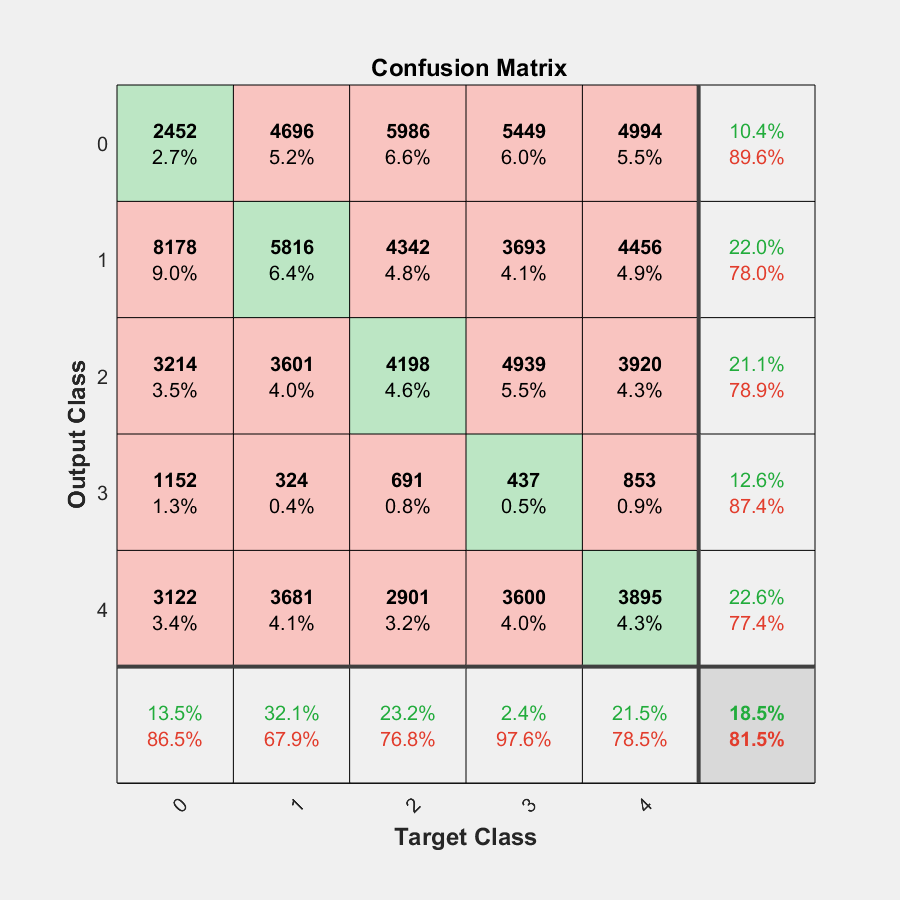

[idx,Centroids] = kmeans(x_tr_part, 5);
len = length(y_ts_part);
prediction = zeros(len,1);
for i = 1:len
    distances = d_euclid(Centroids',x_ts_part(i,:)');
    [~,index] = min(distances);
    prediction(i)=index-1;%to get different clases
end
%plot confusion Matrix
figure;
plotconfusion(categorical(y_ts_part'),categorical(prediction'));


confusion = confusionmat(categorical(prediction'),categorical(y_ts_part'));
precision = diag(confusion)./sum(confusion,2);
recall = diag(confusion)./sum(confusion,1)';
f1Scores = 2*(precision.*recall)./(precision+recall);
meanF1 = mean(f1Scores)

meanF1 = 0.1721